# This file works with the 'GPSData.mlx' file

see 'GPSData.mlx' file for help.

clear all;
close all;
clc;

load GPSdata.mat
load trueNEDdata.mat

truePositionNED = trueNEDdata(:,1:3);
trueVelocityNED = trueNEDdata(:,4:6);
llaV0 = trueVelocityNED(1,1:3);
trueLLAVdata = ned2lla(trueVelocityNED, llaV0, 'flat');

%HoustonLLA = [29.760799, -95.369507, 25];
%AustinLLA = [30.271129, -97.7436995, 500];
lla0 = [29.760799, -95.369507, 25];
trueLLAdata = ned2lla(truePositionNED,lla0,'flat');

npts = 100;

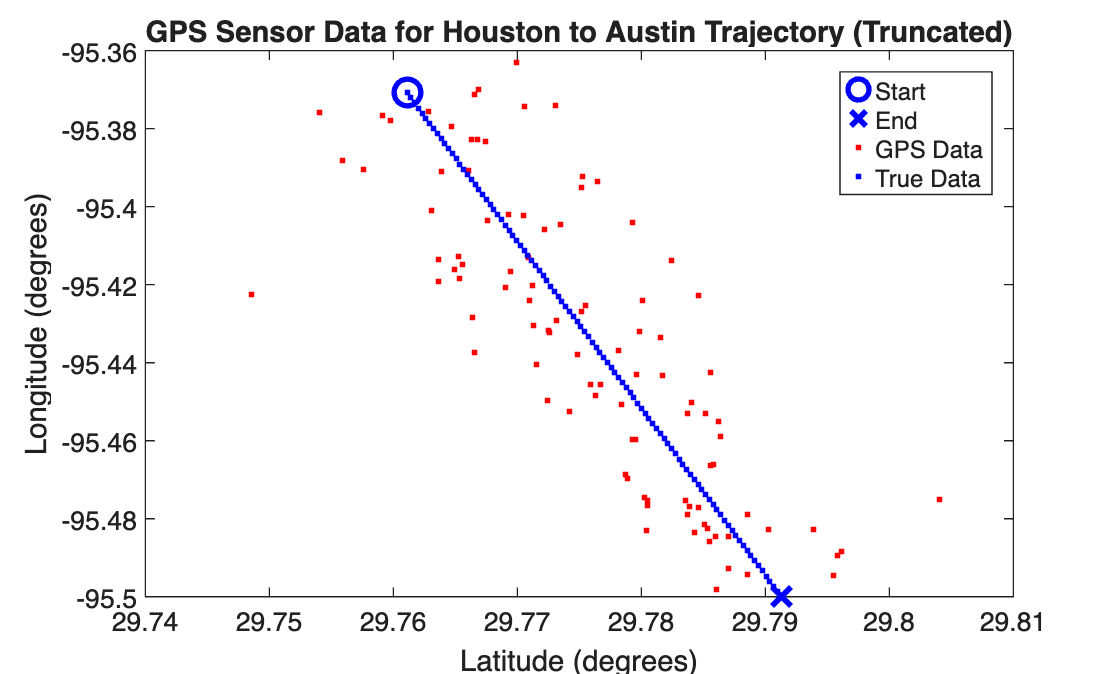

tempGPS = GPSdata(1:npts,1:3);
xGPS = tempGPS(:,1);
yGPS = tempGPS(:,2);

tempTrue = trueLLAdata(1:npts,1:3);
xTrue = tempTrue(:,1);
yTrue = tempTrue(:,2);

figure(1);
plot(xTrue(1),yTrue(1), 'bo', 'DisplayName','Start', 'MarkerSize',10, 'LineWidth',2);
hold on;
title('GPS Sensor Data for Houston to Austin Trajectory (Truncated)')
xlabel('Latitude (degrees)')
ylabel('Longitude (degrees)')
plot(xTrue(end),yTrue(end), 'bx', 'DisplayName','End', 'MarkerSize',10, 'LineWidth',2);
plot(xGPS,yGPS, 'r.', 'DisplayName','GPS Data');
plot(xTrue,yTrue, 'b.', 'DisplayName','True Data')
legend();
hold off;

initialState = [xGPS(1);0;yGPS(1);0];
KF = trackingKF('MotionModel','2D Constant Velocity','State',initialState);
T = 1;
trueData = [xTrue,yTrue];

for k = 1:size(trueData,1)
    pstates(k,:) = predict(KF,T);
    cstates(k,:) = correct(KF,trueData(k,:));
end

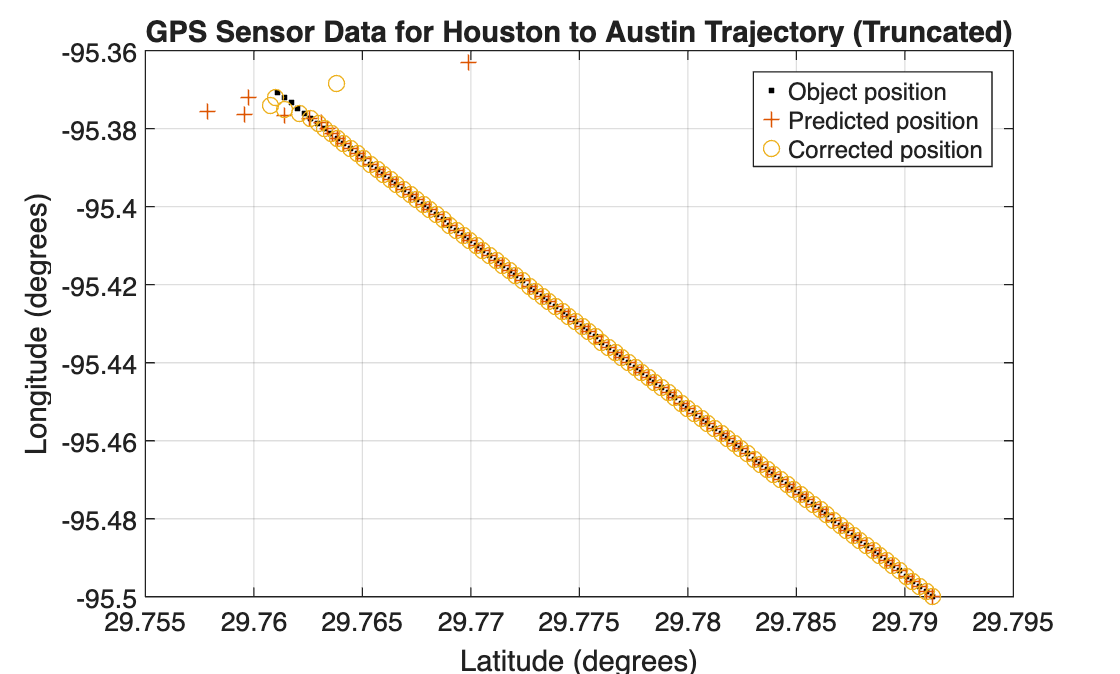

figure(2);
plot(trueData(:,1),trueData(:,2),"k.", ...
    pstates(:,1),pstates(:,3),"+", ...
    cstates(:,1),cstates(:,3),"o")
xlabel('Latitude (degrees)')
ylabel('Longitude (degrees)')
title('GPS Sensor Data for Houston to Austin Trajectory (Truncated)')
grid
xt  = [xGPS(1), trueData(1,1), trueData(end,1)];
yt = [yGPS(1), trueData(1,2), trueData(end,2)];
%text(xt,yt,["First measurement","First position","Last position"])
legend("Object position","Predicted position","Corrected position")